clc; clear all; close all;

% This is Circuit number 9 . R1 = 1800 Ohm , R2 = 1900 Ohm , C1 = 50 microFarad , C2 = 40 microFarad , L1 = 22 Henry , ramp up time, t_RU1 = 1.0 Seconds , max supply voltage U_s1max = 12.0 Volt , C1 initial voltage = 0 Volt , C2 initial voltage = 0 Volt , L1 initial current = 0 Ampere , simulation time = 3.2 Seconds . What is the rms value of the current [milliAmpere] in inductor L1 ?

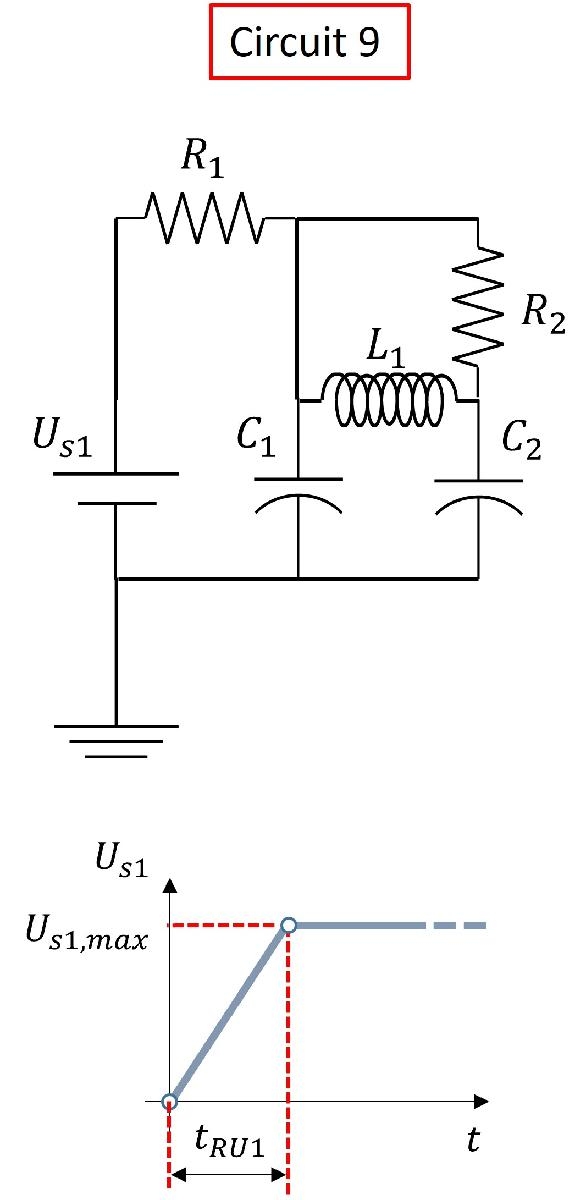

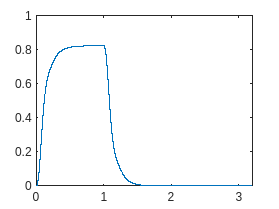

R1 = 1100; % Ohm
R2 = 1500; % Ohm
C1 = 50*10^-6; % F
C2 = 55*10^-6; % F
L1 = 28; % H

t_RU1 = 1; % s
U_s1max = 15; % V
UC1 = 0; % V
UC2 = 0; % V
i4 = 0; % A

simTime = 3.2; % s
t = 0; % s
dt = 10^-5; % s
idx = 1;

while(t <= simTime)
    % Calculation
    if(t < t_RU1)
        Us1 = t/t_RU1 * U_s1max;
    else
        Us1 = U_s1max;
    end

    uA = Us1;
    i3 = (UC1-UC2)/R2;
    i1 = (uA-UC1)/R1;

    i2 = i1-i3-i4;
    i6 = i3+i4;

    i4Dot = 1/L1 * (UC1-UC2);
    UC1Dot = 1/C1 * i2;
    UC2Dot = 1/C2 * i6;

    % Logging
    t_plt(idx) = t;
    i4_plt(idx) = i4*1000;
    Us1_plt(idx) = Us1;

    % Time integration
    i4 = i4 + i4Dot * dt;
    UC1 = UC1 + UC1Dot * dt;
    UC2 = UC2 + UC2Dot * dt;

    % Update variables
    t = t + dt;
    idx = idx + 1;
end

plot(t_plt, i4_plt)

irms = rms(i4_plt)

irms =          0.437296914176548


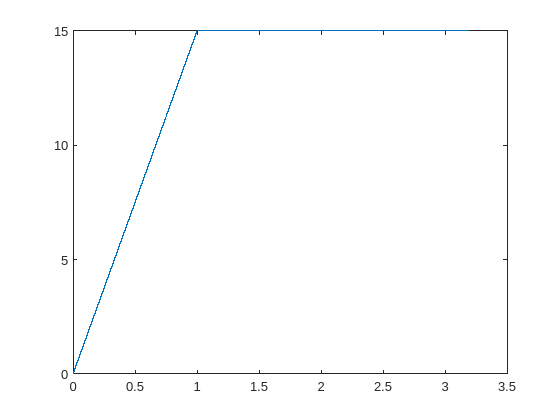


plot(t_plt, Us1_plt)

disp("What is the rms value of the current [milliAmpere] in inductor L1 ?")

What is the rms value of the current [milliAmpere] in inductor L1 ?
